A0 = [1 2 0; 0 3 -5]

A0 =      1     2     0
     0     3    -5


b0 = [20; -10]

b0 =     20
   -10


c0 = [3; 4; -2]

c0 =      3
     4
    -2


Maximization can be converterted to a minimization problem by:

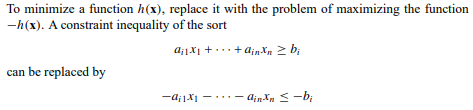

Remove equality constraint by replacing it with two inequality constraints:

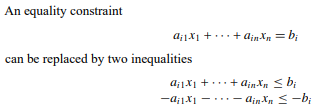

A1 = [-1 4 0; 0 1 -2; 0 -1 2]

A1 =     -1     4     0
     0     1    -2
     0    -1     2


c1 = [7; -3; 1]*-1 %multiplied by -1 because it's a minimization

c1 =     -7
     3
    -1


b1 = [-35; 20; -20] 

b1 =    -35
    20
   -20



%  The two inequalities 
%  x2 - 2x3 <=  20
% -x2 + 2x3 <= -20

**Opgave 15**

The Benri Company manufactures two kinds of kitchen gadgets: invertible widgets and collapsible whammies. The production process is divided into three departments: fabricating, packing, and shipping. The hours of labor required for each operation and the hours available in each department each day are shown below.

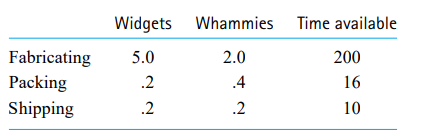

Suppose that the profit on each widget is $20 and the profit on each whammy is $26. How many widgets and how many whammies should be made each day to maximize the company’s profit?

% maximize  20*widget + 26*whammy

% 5.0*widget + 2.0*whammy <= 200
% 0.2*widget + 0.4*whammy <= 16
% 0.2*widget + 0.2*whammy <= 10


%k = [{5*x + 2*y <= 200, 0.2*x + 0.4*y <= 16, 0.2*x + 0.2*y <= 10}, 20*x + 26*y, NonNegative]
%g = linopt:plot_data(k, [x, y])
%plot(g)


A = [5 2; 0.2 0.4; 0.2 0.2]

A =    5.000000000000000   2.000000000000000
   0.200000000000000   0.400000000000000
   0.200000000000000   0.200000000000000


b = [20; 26]

b =     20
    26


lb = zeros(3,1)

lb =      0
     0


ub = [5;5]

ub =      5
     5


c = [200; 16; 10]

c =    200
    16
    10



plot_feasible(A, b, c, lb, ub)

Error using plot_feasible (line 104)
incorrect input sizes\n